# Physics informed neural network

Custom training loop

## Architecture

Nlayers = 2;
Nneurons = Ninputs;
Hactivation = 'reluLayer';
Oactivation = 'tanhLayer';
dropout = 0;
Winitializer = 'narrow-normal';
Binitializer = 'narrow-normal';

PInet = FFNN(Ninputs, Noutputs, Nlayers, Nneurons, Hactivation, Oactivation, dropout, Winitializer, Binitializer).net;
PInet = dlupdate(@double, PInet);

## Training

lambda = 0.9; % Physical loss relative importance [0, 1]
lr_i = 1e-2;
lr_f = 1e-6;
Ec_max = E

Ec_max = 1822500

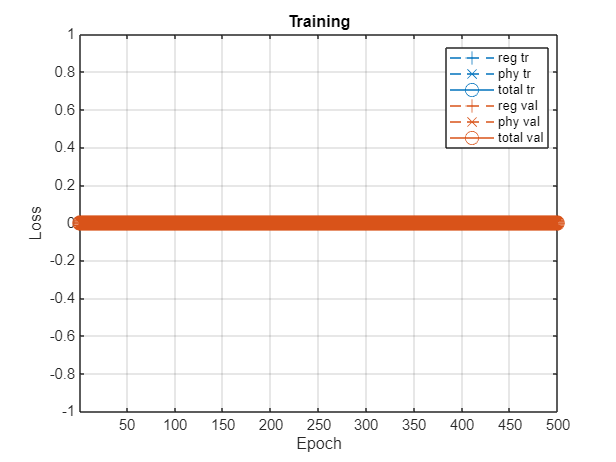

Index in position 1 exceeds array bounds. Index must not exceed 5.
Error in deep.internal.recording.operations.ParenReferenceNonRepeatedSubOp/forward (line 30)
            x = x(Index{:});
Error in  ()  (

plots = true;

PInet = PINNtrain(PInet, dlX_tr, dlY_tr, dlX_val, dlY_val, lr_i, lr_f, plots, Xmax, Ymax, Ec_max, Tl, N, lambda)

## Summary

dlY_tr_pred = forward(PInet, dlX_tr);
dlY_val_pred = forward(PInet, dlX_val);

Y_tr_pred = extractdata(dlY_tr_pred);
Y_val_pred = extractdata(dlY_val_pred);

[reg_loss_tr, phy_loss_tr, total_loss_tr, ~] = dlfeval(@customLoss, dlX_tr, dlY_tr, PInet, Xmax, Ymax, Ec_max, Tl, N, lambda);
[reg_loss_val, phy_loss_val, total_loss_val, ~] = dlfeval(@customLoss, dlX_val, dlY_val, PInet, Xmax, Ymax, Ec_max, Tl, N, lambda);

disp('Train loss');
disp(['Regression: ' num2str(extractdata(reg_loss_tr)) ', Physics: ' num2str(extractdata(phy_loss_tr)) ', Total: ' num2str(extractdata(total_loss_tr))]);
disp('Validation loss');
disp(['Regression: ' num2str(extractdata(reg_loss_val)) ', Physics: ' num2str(extractdata(phy_loss_val)) ', Total: ' num2str(extractdata(total_loss_val))]);

analyzeNetwork(PInet);
summary(PInet)

# Performance analysis

## Complete timeseries

pred = extractdata(forward(PInet, dlX));
figure
subplot(ceil(Noutputs/3), 3, 1)
stairs(1:Nsamples, Y(1, :))
hold on
stairs(1:Nsamples, pred(1, :))
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    stairs(1:Nsamples, Y(idx, :))
    hold on
    stairs(1:Nsamples, pred(idx, :))
    hold off
end
sgtitle('Complete timeseries');

## Error histogram

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 10, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 10, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

weights_input_hidden = PInet.Learnables.Value;
weights_input_hidden = extractdata(weights_input_hidden{3});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(max(abs(weights_input_hidden)))
weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));